% get chart value experiments
truecard = imread('color_testchart.jpg');
imshow(truecard)

[h, w, c] = size(truecard)
I1 = truecard(68:1045, 68:1527, :);
imshow(I1)

[h, w, c] = size(I1)
h_offset = h/4
w_offset = w/6
for i = 1:4
    for j = 1:6
        row = round((h_offset*i) - (h_offset/2));
        col = round((w_offset*j) - (w_offset/2));
        RGB((i-1)*6 + j, :) = I1(row, col, :);
    end
end

RGB

% chart correction experiments
% test example 1 - reduce all red tones by 50% (cyan colored)
truecard = imread('color_testchart.jpg');
badtestcard = truecard;
badtestcard(:,:,1) = 0.5*badtestcard(:,:,1);

RGB_truechart = get_chart_values(truecard);
RGB_badchart = get_chart_values(badtestcard);

% red channel visualization
deg = 23;                        
x = RGB_badchart(:, 1);         
y = RGB_truechart(:, 1);        

p = polyfit(x, y, deg);
disp(p);
levels = (0:255)';  
predicted = polyval(p, x);                 % 24 predicted values
err = mean(abs(predicted - y))             % average error
Rfit = polyval(p, levels);        
disp(Rfit)

figure
plot(x, y, 'o')                   % the 24 dots
hold on
plot(levels, Rfit, 'r-')           % the fitted curve
plot([0 255], [0 255], 'k--')     % "no change" diagonal
xlabel('bad value')
ylabel('good value')
title('Red channel')
legend('chart patches', 'fitted curve', 'no change')
axis([0 255 0 255])

% green channel visualization
deg = 6;                        
x = RGB_badchart(:, 2);         
y = RGB_truechart(:, 2);        

p = polyfit(x, y, deg);
levels = (0:255)';               
Gfit = polyval(p, levels);  
disp(fit)

figure
plot(x, y, 'o')                   % the 24 dots
hold on
plot(levels, Gfit, 'r-')           % the fitted curve
plot([0 255], [0 255], 'k--')     % "no change" diagonal
xlabel('bad value')
ylabel('good value')
title('Green channel')
legend('chart patches', 'fitted curve', 'no change')
axis([0 255 0 255])

% blue channel visualization
deg = 6;                        
x = RGB_badchart(:, 3);         
y = RGB_truechart(:, 3);        

p = polyfit(x, y, deg);
levels = (0:255)';               
Bfit = polyval(p, levels);  
disp(fit)

figure
plot(x, y, 'o')                   % the 24 dots
hold on
plot(levels, Bfit, 'r-')           % the fitted curve
plot([0 255], [0 255], 'k--')     % "no change" diagonal
xlabel('bad value')
ylabel('good value')
title('Blue channel')
legend('chart patches', 'fitted curve', 'no change')
axis([0 255 0 255])

% join all each channels into 1 matrix
RGB_map = [Rfit, Gfit, Bfit];

% round off values and clip values greater than 255 and less than 0
RGB_map = round(RGB_map);    
RGB_map = max(RGB_map, 0);       
RGB_map = min(RGB_map, 255);

trueimage = imread('color_toys.jpg');
badimage = trueimage;
badimage(:,:,1) = 0.5*badimage(:,:,1);
figure
imshow(badimage)

%uint8 can only hold 0-255 but the mapping holds 1-256 rows hence convert
%to double so when we add 1 it goes to 256th index
badimage = double(badimage)

[h, w, c] = size(badimage)
adjusted_image = zeros(h, w, c, 'uint8');

for i = 1:h
    for j = 1:w
        for k = 1:c
        map_index = badimage(i, j, k) + 1;
        new_value = RGB_map(map_index, k);
        adjusted_image(i, j, k) = new_value;
        end
    end
end

imshow(adjusted_image)

% chart correction experiments
% test example 2 - reduce min max range and skew colors too (coffee
% colored)
truecard = imread('color_testchart.jpg');
badtestcard = truecard;
badtestcard(:,:,1) = 0.5*badtestcard(:,:,1);
badtestcard(:,:,3) = 0.7*badtestcard(:,:,3);
badtestcard = 0.5*badtestcard + 32;

RGB_truechart = get_chart_values(truecard);
RGB_badchart = get_chart_values(badtestcard);

% red channel visualization
deg = 3;                        
x = RGB_badchart(:, 1);         
y = RGB_truechart(:, 1);        

p = polyfit(x, y, deg);
disp(p);

   -0.0000    0.0043    3.7595 -125.6070



levels = (0:255)';  
predicted = polyval(p, x);                 % 24 predicted values
err = mean(abs(predicted - y))             % average error

err = 1.0182

Rfit = polyval(p, levels);        
disp(Rfit);

 -125.6070
 -121.8433
 -118.0711
 -114.2907
 -110.5021
 -106.7055
 -102.9010
  -99.0887
  -95.2689
  -91.4416
  -87.6069
  -83.7651
  -79.9162
  -76.0604
  -72.1979
  -68.3286
  -64.4529
  -60.5708
  -56.6825
  -52.7881
  -48.8877
  -44.9815
  -41.0697
  -37.1523
  -33.2295
  -29.3014
  -25.3682
  -21.4300
  -17.4870
  -13.5392
   -9.5869
   -5.6301
   -1.6690
    2.2962
    6.2655
   10.2386
   14.2155
   18.1960
   22.1800
   26.1674
   30.1579
   34.1515
   38.1480
   42.1473
   46.1493
   50.1538
   54.1606
   58.1697
   62.1809
   66.1940
   70.2090
   74.2257
   78.2439
   82.2635
   86.2844
   90.3064
   94.3295
   98.3534
  102.3780
  106.4032
  110.4288
  114.4548
  118.4809
  122.5071
  126.5332
  130.5590
  134.5844
  138.6094
  142.6337
  146.6571
  150.6797
  154.7012
  158.7215
  162.7405
  166.7579
  170.7738
  174.7879
  178.8001
  182.8103
  186.8183
  190.8240
  194.8273
  198.8280
  202.8260
  206.8211
  210.8132
  214.8022
  218.7879
  222.7703
  226.7491
  230.7242

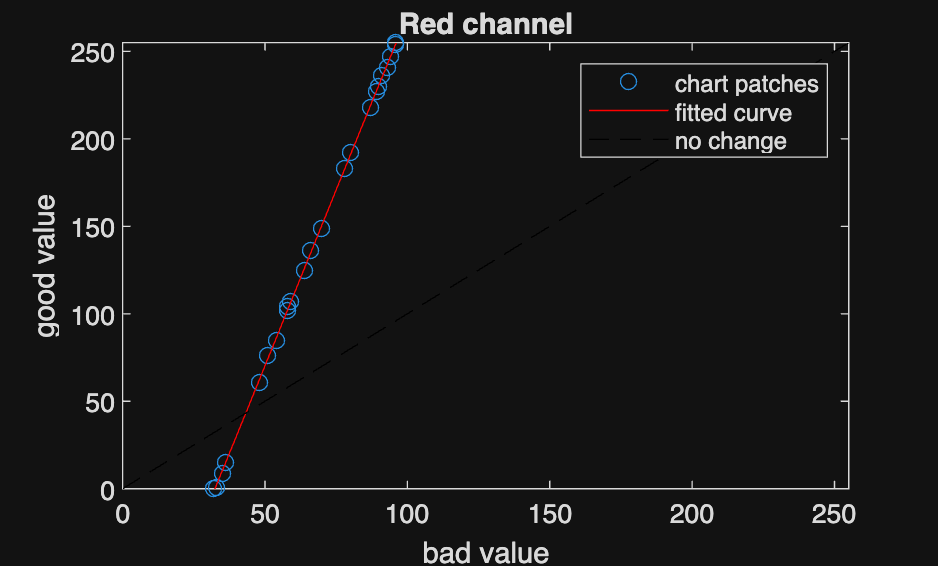


figure
plot(x, y, 'o')                   % the 24 dots
hold on
plot(levels, Rfit, 'r-')           % the fitted curve
plot([0 255], [0 255], 'k--')     % "no change" diagonal
xlabel('bad value')
ylabel('good value')
title('Red channel')
legend('chart patches', 'fitted curve', 'no change')
axis([0 255 0 255])


% green channel visualization
deg = 1;                        
x = RGB_badchart(:, 2);         
y = RGB_truechart(:, 2);        

p = polyfit(x, y, deg);
levels = (0:255)';               
Gfit = polyval(p, levels);  
disp(fit)

    0.0000
    1.0000
    2.0000
    3.0000
    4.0000
    5.0000
    6.0000
    7.0000
    8.0000
    9.0000
   10.0000
   11.0000
   12.0000
   13.0000
   14.0000
   15.0000
   16.0000
   17.0000
   18.0000
   19.0000
   20.0000
   21.0000
   22.0000
   23.0000
   24.0000
   25.0000
   26.0000
   27.0000
   28.0000
   29.0000
   30.0000
   31.0000
   32.0000
   33.0000
   34.0000
   35.0000
   36.0000
   37.0000
   38.0000
   39.0000
   40.0000
   41.0000
   42.0000
   43.0000
   44.0000
   45.0000
   46.0000
   47.0000
   48.0000
   49.0000
   50.0000
   51.0000
   52.0000
   53.0000
   54.0000
   55.0000
   56.0000
   57.0000
   58.0000
   59.0000
   60.0000
   61.0000
   62.0000
   63.0000
   64.0000
   65.0000
   66.0000
   67.0000
   68.0000
   69.0000
   70.0000
   71.0000
   72.0000
   73.0000
   74.0000
   75.0000
   76.0000
   77.0000
   78.0000
   79.0000
   80.0000
   81.0000
   82.0000
   83.0000
   84.0000
   85.0000
   86.0000
   87.0000
   88.0000
   89.0000
   90.0000

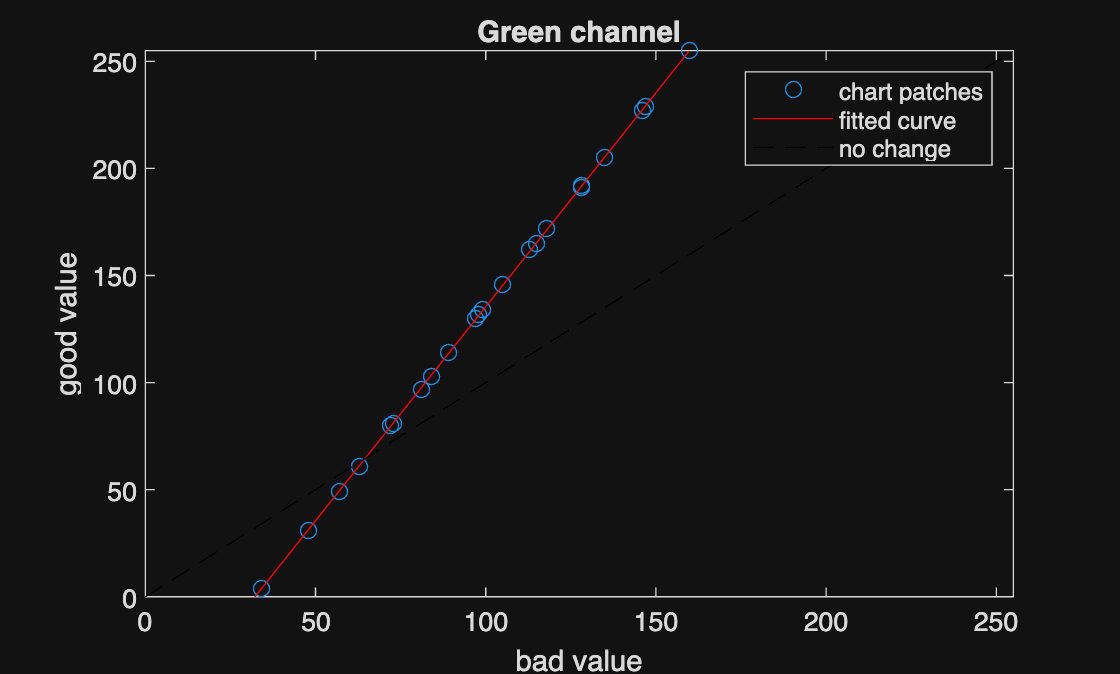


figure
plot(x, y, 'o')                   % the 24 dots
hold on
plot(levels, Gfit, 'r-')           % the fitted curve
plot([0 255], [0 255], 'k--')     % "no change" diagonal
xlabel('bad value')
ylabel('good value')
title('Green channel')
legend('chart patches', 'fitted curve', 'no change')
axis([0 255 0 255])


% blue channel visualization
deg = 1;                        
x = RGB_badchart(:, 3);         
y = RGB_truechart(:, 3);        

p = polyfit(x, y, deg);
levels = (0:255)';               
Bfit = polyval(p, levels);  
disp(fit)

    0.0000
    1.0000
    2.0000
    3.0000
    4.0000
    5.0000
    6.0000
    7.0000
    8.0000
    9.0000
   10.0000
   11.0000
   12.0000
   13.0000
   14.0000
   15.0000
   16.0000
   17.0000
   18.0000
   19.0000
   20.0000
   21.0000
   22.0000
   23.0000
   24.0000
   25.0000
   26.0000
   27.0000
   28.0000
   29.0000
   30.0000
   31.0000
   32.0000
   33.0000
   34.0000
   35.0000
   36.0000
   37.0000
   38.0000
   39.0000
   40.0000
   41.0000
   42.0000
   43.0000
   44.0000
   45.0000
   46.0000
   47.0000
   48.0000
   49.0000
   50.0000
   51.0000
   52.0000
   53.0000
   54.0000
   55.0000
   56.0000
   57.0000
   58.0000
   59.0000
   60.0000
   61.0000
   62.0000
   63.0000
   64.0000
   65.0000
   66.0000
   67.0000
   68.0000
   69.0000
   70.0000
   71.0000
   72.0000
   73.0000
   74.0000
   75.0000
   76.0000
   77.0000
   78.0000
   79.0000
   80.0000
   81.0000
   82.0000
   83.0000
   84.0000
   85.0000
   86.0000
   87.0000
   88.0000
   89.0000
   90.0000

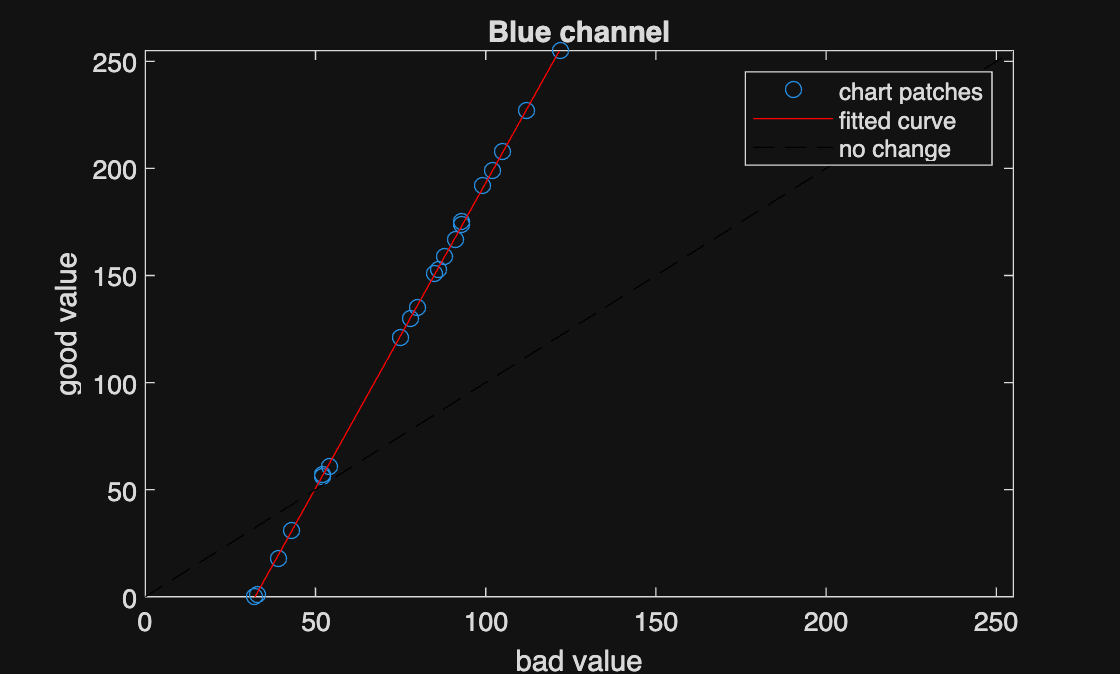


figure
plot(x, y, 'o')                   % the 24 dots
hold on
plot(levels, Bfit, 'r-')           % the fitted curve
plot([0 255], [0 255], 'k--')     % "no change" diagonal
xlabel('bad value')
ylabel('good value')
title('Blue channel')
legend('chart patches', 'fitted curve', 'no change')
axis([0 255 0 255])


% join all each channels into 1 matrix
RGB_map = [Rfit, Gfit, Bfit];

% round off values and clip values greater than 255 and less than 0
RGB_map = round(RGB_map);    
RGB_map = max(RGB_map, 0);       
RGB_map = min(RGB_map, 255);

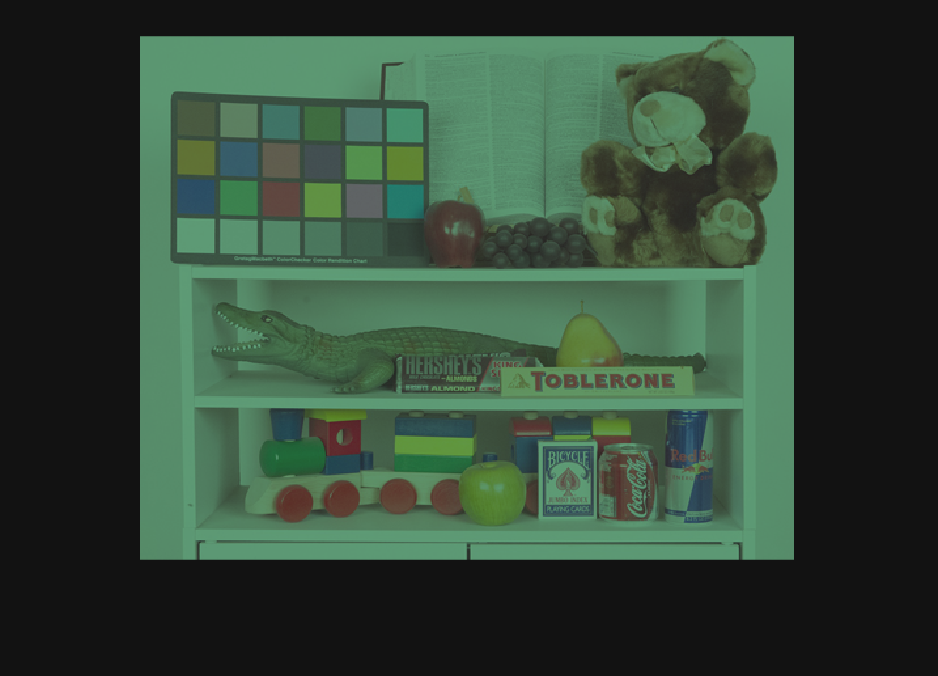

trueimage = imread('color_toys.jpg');
badimage = trueimage;
badimage(:,:,1) = 0.5*badimage(:,:,1);
badimage(:,:,3) = 0.7*badimage(:,:,3);
badimage = 0.5*badimage + 32;
figure
imshow(badimage)


%uint8 can only hold 0-255 but the mapping holds 1-256 rows hence convert
%to double so when we add 1 it goes to 256th index
badimage = double(badimage)

badimage = badimage(:,:,1) =

    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    92    92    92    92    92    92    92    91    92    92    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91    92    92    92    91    91    91    91    91    91    92    92    91    91    92    92    92    92    92    92    92    91    91    91    91    92    92    92    92    91    91    92    92    92    91    91    91    91    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    92    


[h, w, c] = size(badimage)

h = 400

w = 500

c = 3

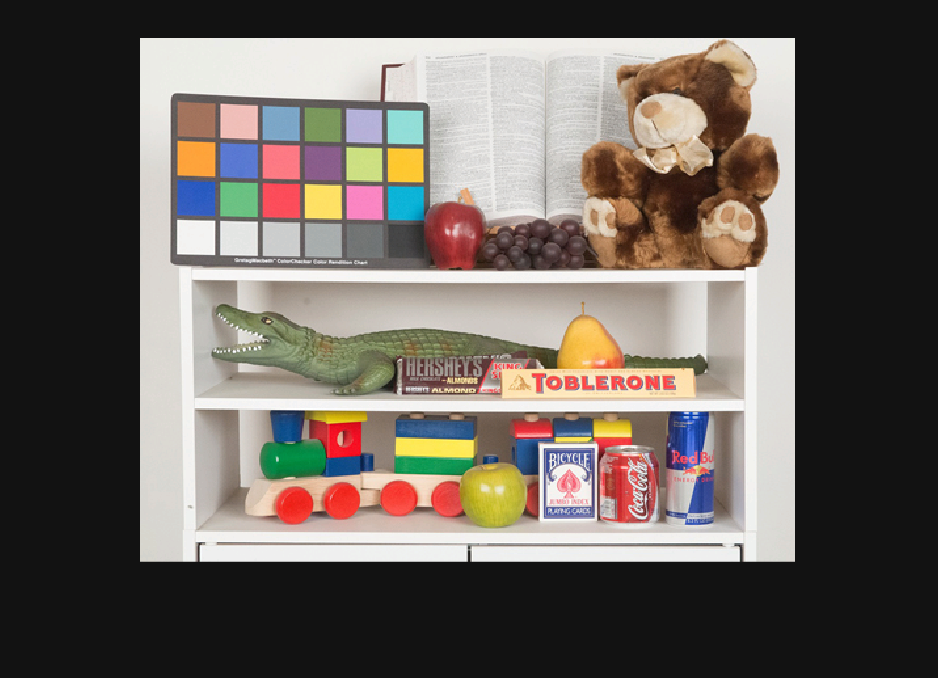

adjusted_image = zeros(h, w, c, 'uint8');

for i = 1:h
    for j = 1:w
        for k = 1:c
        map_index = badimage(i, j, k) + 1;
        new_value = RGB_map(map_index, k);
        adjusted_image(i, j, k) = new_value;
        end
    end
end

imshow(adjusted_image)